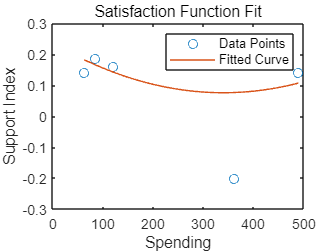

clear, clc;

% 数据点
people_number = [690648, 741500, 959000, 1306000, 117000, 1167000, 1670000]';
spending = [62.116992, 84.666912, 120.815744, 361.761984, 301.421984, 381.794864, 490]';
support_index = [0.139784946, 0.186813187, 0.161290323, -0.20212766, 0.221052632, 0.182795699, 0.139784946]';

% 拟合满意度函数
p = polyfit(spending, support_index, 2); % 二次多项式拟合

% 显示拟合结果
x_fit = linspace(min(spending), max(spending), 100);
y_fit = polyval(p, x_fit);
figure;
plot(spending, support_index, 'o', x_fit, y_fit, '-');
xlabel('Spending');
ylabel('Support Index');
title('Satisfaction Function Fit');
legend('Data Points', 'Fitted Curve');

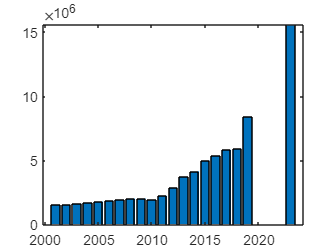


% 导入并预处理数据
data = load("data2.mat");
data = table2array(data.data);
data(20, 2) = NaN; data(21, 2) = NaN; data(22, 2) = NaN;
bar(data(:, 1), data(:, 2));

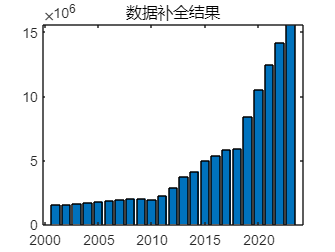


% 数据补全
chazhi_fa = char('linear', 'spline', 'pchip', 'movmean');
choice_2 = 3;
if choice_2 ~= 4
    data = fillmissing(data, strtrim(chazhi_fa(choice_2, :)));
else
    data = fillmissing(data, 'movmean', 10);
end
bar(data(:, 1), data(:, 2));
title('数据补全结果');

ADF检验结果:
是否拒绝原假设（序列非平稳）: 0
p值: 0.9990
KPSS检验结果:
是否拒绝原假设（序列平稳）: 0
p值: 0.0100


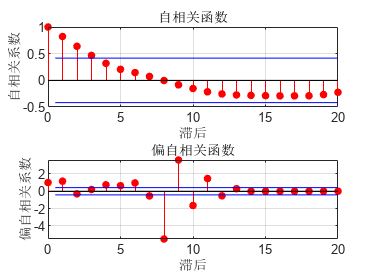

 
    ARIMA(2,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic     PValue  
                __________    _____________    __________    _________

    Constant     6.412e+05     5.0073e+05          1.2805      0.20036
    AR{1}         -0.30455        0.52892         -0.5758      0.56475
    AR{2}          0.69545        0.46731          1.4882       0.1367
    MA{1}                1        0.33541          2.9814    0.0028692
    Variance    5.8574e+11        0.70891      8.2626e+11            0




% 时间序列预测测试
y = data(:, 2); PreTime = 100;
forecastTest = ARIMA(PreTime, y);

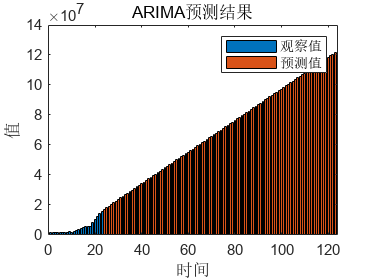

figure; bar(y); hold on;
time_axis = (length(y) + 1:length(y) + PreTime)';
bar(time_axis, forecastTest);
xlabel('时间'); ylabel('值');
legend('观察值', '预测值'); title('ARIMA预测结果');


% 优化模型
f = @(alpha) -Revenue1(alpha, PreTime, p);
x0 = [1e5; 0 * ones(PreTime, 1); 0 * ones(PreTime, 1)];
A = [zeros(PreTime, 1), eye(PreTime), eye(PreTime)];
b = 0.5 * ones(PreTime, 1);
lb = zeros(2 * PreTime + 1, 1); ub = [1e9; 0.5 * ones(2 * PreTime, 1)];
[x, fmin] = fmincon(f, x0, A, b, [], [], lb, ub);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


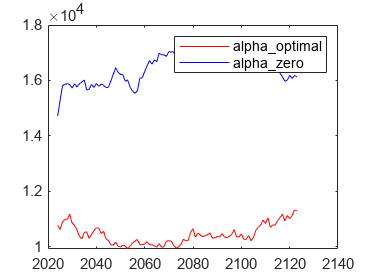

Nmax = x(1);
alpha = [x(2:PreTime+1), x(PreTime+2:end)];
[R, Rt, S, C, I, N] = Revenue1(x, PreTime, p);
[R0, Rt0, S0] = Revenue1([1e5; linspace(0.03, 0, 3)'; 0 * ones(97, 1); linspace(0.03, 0, 3)'; 0 * ones(97, 1)], PreTime, p);
figure; plot(2024:2023+PreTime, Rt, 'r', 2024:2023+PreTime, Rt0, 'b');
legend('alpha\_optimal', 'alpha\_zero');


% 目标函数（1）

function [R, Rt, S, C, I, N] = Revenue1(alpha, PreTime, p)
    % 参数
    Nmax = alpha(1);
    alpha_1 = alpha(2:1 + PreTime);
    alpha_2 = alpha(2 + PreTime:end);
    P0 = 490 / 1.67; N0 = 1.67e6; S0 = 0.5; Ep = -1;
    Cmean = 14.4; Imean = 1; C0 = 1e5; I0 = 1e5;
    r1 = 2 / pi; r2 = 1e-4; k1 = 100; k2 = 100;
    lambda = [0.1; 0.8; 0.1];

    N = zeros(PreTime, 1); Rt = zeros(PreTime, 1);
    S = zeros(PreTime, 1); I = zeros(PreTime, 1);
    C = zeros(PreTime, 1);

    N(1) = N0 * (1 + alpha_1(1) + alpha_2(1))^Ep + 0.5 * randn(1);
    N(1) = min([Nmax, r1 * N(1) * atan(r2 * S0)]);
    Rt(1) = P0 * N(1);

    I(1) = I0 + k2 * alpha_2(1) * P0 * N(1); C(1) = Cmean * N(1);
    S(1) = [C0 / Cmean * N(1), I(1) / Imean * N(1), Rt(1) / N(1)] * lambda;
    for t = 2:PreTime
        N(t) = N(t-1) * ((1 + alpha_1(t) + alpha_2(t)) / (1 + alpha_1(t-1) + alpha_2(t-1)))^Ep + 0.5 * randn(1);
        N(t) = min([Nmax, r1 * N(t) * atan(r2 * S(t-1))]);
        Rt(t) = P0 * N(t);

        C(t) = Cmean * N(t) - k1 * alpha_1(t-1) * P0 * N(t-1);
        I(t) = I(t-1) + k2 * alpha_2(t-1) * P0 * N(t-1);
        S(t) = [C0 / C(t), I(t) / Imean * N(t), Rt(t) / N(t)] * lambda;
    end
    R = sum(Rt);
end

% ARIMA算法
function forecastTest = ARIMA(PreTime, y)
    % 检查数据长度
    if length(y) < 10
        error('数据长度不足，无法进行ARIMA预测');
    end

    % 拆分数据集为训练集和测试集
    train_size = floor(0.8 * length(y));
    train_data = y;

    % 平稳性检验 - ADF检验
    [h_adf, p_adf] = adftest(y);
    fprintf('ADF检验结果:\n');
    fprintf('是否拒绝原假设（序列非平稳）: %d\n', h_adf);
    fprintf('p值: %.4f\n', p_adf);

    % 平稳性检验 - KPSS检验
    [h_kpss, p_kpss] = kpsstest(y);
    fprintf('KPSS检验结果:\n');
    fprintf('是否拒绝原假设（序列平稳）: %d\n', ~h_kpss);
    fprintf('p值: %.4f\n', p_kpss);

    % 确定参数
    y_diff = train_data;
    figure;
    subplot(2, 1, 1);
    autocorr(y_diff);
    title('自相关函数');
    xlabel('滞后');
    ylabel('自相关系数');
    subplot(2, 1, 2);
    parcorr(y_diff);
    title('偏自相关函数');
    xlabel('滞后');
    ylabel('偏自相关系数');

    % 训练ARIMA模型
    model = arima(2, 1, 1);
    model = estimate(model, y_diff);

    % 测试未来时间预测情况
    horizon = PreTime;
    [forecastTest, YMSE, forecastCI] = forecast(model, horizon, 'Y0', y_diff);
end